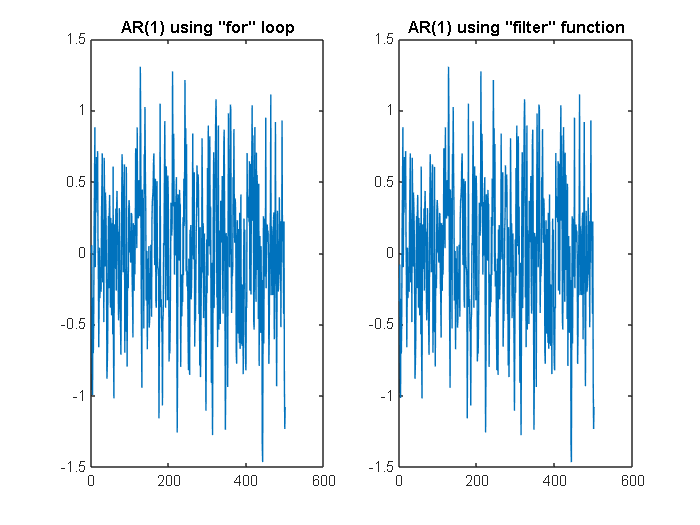

% EXERCISE 1
% parameters 
T=500;         % number of observations 
phi=.4;        % value of phi 
e=randn(T,1)*sqrt(.2);  % white noise process 
x = zeros(T, 1);  % Preallocate x to hold T observations
% using for 
for t=2:T
    x(t)=phi*x(t-1)+e(t);
end

% using "filter"
 y=filter(1,[1,-phi],e);

% plot of the results 
subplot(1,2,1)
plot(x)
title('AR(1) using "for" loop')
subplot(1,2,2)
plot(y)
title('AR(1) using "filter" function')